2.11    (PageRank和马尔可夫链）实时脚本

由张志涌编写、修改于 2023.1。

U = {'http://www.alpha.com'
     'http://www.beta.com'
     'http://www.gamma.com'
     'http://www.delta.com'
     'http://www.rho.com'
     'http://www.sigma.com'}

U = 6×1 cell 数组
    {'http://www.alpha.com'}
    {'http://www.beta.com' }
    {'http://www.gamma.com'}
    {'http://www.delta.com'}
    {'http://www.rho.com'  }
    {'http://www.sigma.com'}


i = [ 2 6 3 4 4 5 6 1 1];
j = [ 1 1 2 2 3 3 3 4 6];
n = 6;
G = sparse(i,j,1,n,n)

G =    (2,1)        1
   (6,1)        1
   (3,2)        1
   (4,2)        1
   (4,3)        1
   (5,3)        1
   (6,3)        1
   (1,4)        1
   (1,6)        1


full(G)

ans =      0     0     0     1     0     1
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     1     1     0     0     0
     0     0     1     0     0     0
     1     0     1     0     0     0


c = full(sum(G))

c =      2     2     3     1     0     1


p = 0.85; e = ones(n,1); k = find(c~=0);
D = sparse(k,k,1./c(k),n,n);
I = speye(n,n);
x = (I - p*G*D)\e;
x = x/sum(x)

x =     0.3210
    0.1705
    0.1066
    0.1368
    0.0643
    0.2007


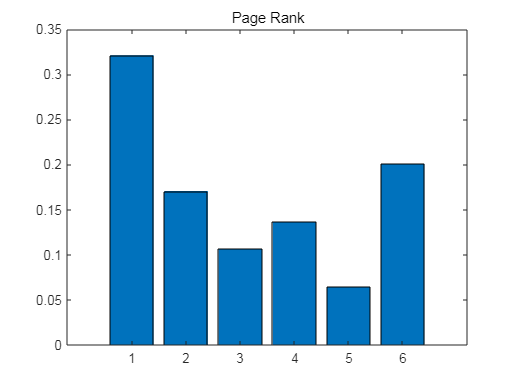

bar(x);
title('Page Rank')

r=full(sum(G,2));
   [~,q] = sort(-x);
   disp('     page-rank  in  out  url')

     page-rank  in  out  url


   k = 1;
   while (k <= n) && (x(q(k)) >= .005)
      j = q(k);
      fprintf(' %3.0f %8.4f %4.0f %4.0f  %s\n', ...
         j,x(j),r(j),c(j),U{j})
      k = k+1;
   end

   1   0.3210    2    2  http://www.alpha.com
   6   0.2007    2    1  http://www.sigma.com
   2   0.1705    1    2  http://www.beta.com
   4   0.1368    2    1  http://www.delta.com
   3   0.1066    1    3  http://www.gamma.com
   5   0.0643    1    0  http://www.rho.com


delta=(1-p)/n;
C=ones(n,1)*c;
A=p*G./C+delta;
A(:,c==0)=1/n 

A =     0.0250    0.0250    0.0250    0.8750    0.1667    0.8750
    0.4500    0.0250    0.0250    0.0250    0.1667    0.0250
    0.0250    0.4500    0.0250    0.0250    0.1667    0.0250
    0.0250    0.4500    0.3083    0.0250    0.1667    0.0250
    0.0250    0.0250    0.3083    0.0250    0.1667    0.0250
    0.4500    0.0250    0.3083    0.0250    0.1667    0.0250


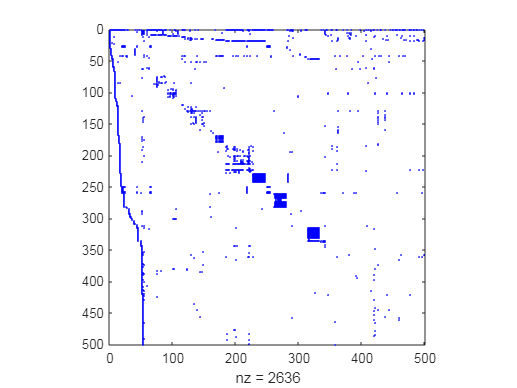

load harvard500
spy(G,'b')

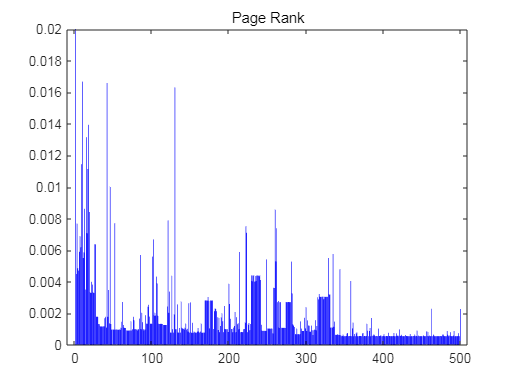

     page-rank  in  out  url
   1   0.0843  195   26  http://www.harvard.edu
  10   0.0167   21   18  http://www.hbs.edu
  42   0.0166   42    0  http://search.harvard.edu:8765/custom/query.html
 130   0.0163   24   12  http://www.med.harvard.edu
  18   0.0139   45   46  http://www.gse.harvard.edu
  15   0.0131   16   49  http://www.hms.harvard.edu
   9   0.0114   21   27  http://www.ksg.harvard.edu
  17   0.0111   13    6  http://www.hsph.harvard.edu
  46   0.0100   18   21  http://www.gocrimson.com
  13   0.0086    9    1  http://www.hsdm.med.harvard.edu
 260   0.0086   26    1  http://search.harvard.edu:8765/query.html
  19   0.0084   23   21  http://www.radcliffe.edu
 121   0.0079    1    3  http://www.hsdm.harvard.edu
  52   0.0077   11    2  http://whitepages.med.harvard.edu
   3   0.0077   21   12  http://lib.harvard.edu
 222   0.0075   36   34  http://www.gse.harvard.edu/sitemap.html
 262   0.0074   20    3  http://www.dana-farber.org
 223   0.0071   36   10  http://www.gse.har

pagerank(U,G);